axis 坐标轴相关

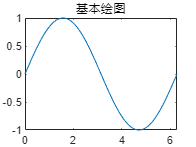

clc
clear all
close all

f = figure();
x = linspace(0,2*pi);
y = sin(x);
plot(x,y,'-');
title("基本绘图")

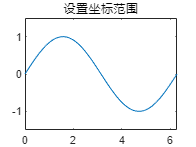


%%%%%%%%%%%%%%%%%%
f1 = figure();
plot(x,y,'-');
% 更改坐标范围
axis([0 2*pi -1.5 1.5])
title("设置坐标范围")

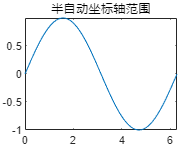


%%%%%%%%%%%%%%%%%%
f2 = figure();
plot(x,y,'-');
% 半自动坐标轴范围，由数据自行计算
axis([0 2*pi -1 inf])
title("半自动坐标轴范围")

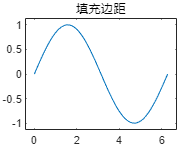


%%%%%%%%%%%%%%%%%%
f3 = figure();
plot(x,y,'-');
% 为坐标区的曲线添加边距填充
axis padded
title("填充边距")

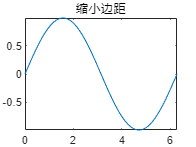


%%%%%%%%%%%%%%%%%%
f4 = figure();
plot(x,y,'-');
% 使坐标区曲线紧凑，靠近坐标轴
axis tight
title("缩小边距")

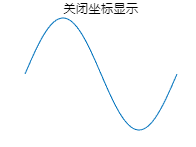


%%%%%%%%%%%%%%%%%%
f5 = figure();
plot(x,y,'-');
% 关闭坐标区背景
axis off
title("关闭坐标显示")

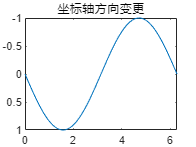


%%%%%%%%%%%%%%%%%%
f6 = figure();
plot(x,y,'-');
% 更改坐标系的方向
% 默认 x 从左到右增加，y从下到上增加
axis ij
title("坐标轴方向变更")

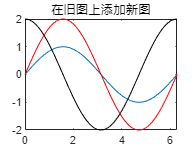


%%%%%%%%%%%%%%%%%%
f7 = figure();
plot(x,y,'-');
y1 = 2*sin(x);
% 保持图像并添加新图像
hold on
plot(x,y1,'r-')
title("在旧图上添加新图")
y2 = 2*cos(x);
plot(x,y2,'k-')
% 调用 hold off 关闭后才会绘制新图窗
hold off

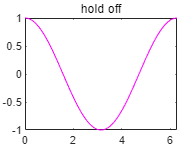

y3 = cos(x);
plot(x,y3,'m-')
title("hold off")

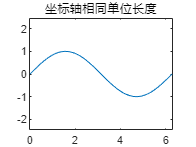



%%%%%%%%%%%%%%%%%%
f8 = figure();
plot(x,y,'-');
% 坐标轴相同单位长度
axis equal
title("坐标轴相同单位长度")

%%%%%%%%%%%%%%%%%%
% 多个坐标轴的坐标轴范围设置
tiledlayout(2,1)

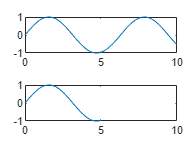

x1 = linspace(0,10,100);
y1 = sin(x1);
ax1 = nexttile;
plot(ax1,x1,y1)

x2 = linspace(0,5,100);
y2 = sin(x2);
ax2 = nexttile;
plot(ax2,x2,y2)

axis([ax1 ax2],[0 10 -1 1])

xlim 坐标轴范围设置

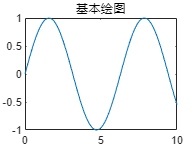

clc
clear all
close all

f = figure();
x = linspace(0,10);
y = sin(x);
plot(x,y)
title("基本绘图")

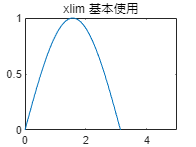


%%%%%%%%%%%%%%%%%%
% xlim 的基本使用
f1 = figure();
plot(x,y)
title("xlim 基本使用")
xlim([0 5])
ylim([0 1])

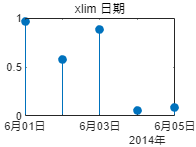



%%%%%%%%%%%%%%%%%%
% 设置具有日期值的坐标范围
f2 = figure();
t = datetime(2014,06,1) + caldays(0:10);
y = rand(11,1);
stem(t,y,'filled')

tstart = datetime(2014,06,1);
tend = datetime(2014,06,5);
xlim([tstart tend])
title("xlim 日期")

grid 控制绘图窗口的坐标区网格线显示

clc
clear all
close all

f = figure();
x = linspace(0,10);
y = sin(x);
plot(x,y)
title("基本绘图")

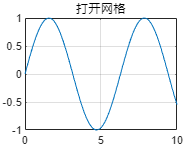


%%%%%%%%%%%%%%%%%%
% 网格可见性设置
f1 = figure();
plot(x,y);
grid on;
title("打开网格")

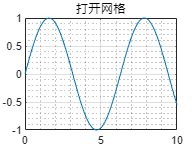


%%%%%%%%%%%%%%%%%%
% 主次网格显示
f2 = figure();
plot(x,y);
grid on;
grid minor
title("打开网格")

title 为绘图添加标题

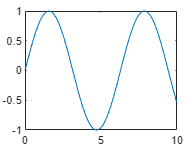

clc
clear all
close all

f = figure();
x = linspace(0,10);
y = sin(x);
plot(x,y)

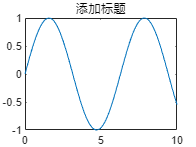


%%%%%%%%%%%%%%%%%%
% 添加标题
f1 = figure();
plot(x,y);
title("添加标题")

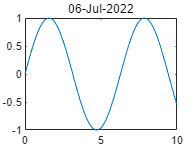


%%%%%%%%%%%%%%%%%%
% 使用返回文本作为标题
f2 = figure();
plot(x,y);
title(date)


%%%%%%%%%%%%%%%%%%
% 创建标题和副标题
f3 = figure();
plot(x,y);
% 使用 t 修改标题，使用 s 修改副标题。
[t,s] = title('Main title','sub title','Color','blue');

%%%%%%%%%%%%%%%%%%
f4 = figure();
plot(x,y);

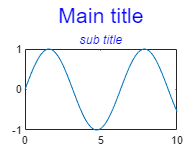

% 设置属性
t.FontSize = 16;
s.FontAngle = 'italic';

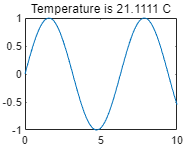


%%%%%%%%%%%%%%%%%%
f5 = figure();
plot(x,y);
f = 70;
c = (f-32)/1.8;
% 标题包含变量
title(['Temperature is ',num2str(c),' C'])